# **Does Everyone Die?**

The answer is of course yes. But it is of intense interest to us when we die. To this end there are several models to estimate the number of diseased and of removed (dead or immune). The first one is as follows. 

## Model 1


$$\begin{cases} \frac{\it{d}\text{S}}{\it{dt}} = -\beta \, \text{IS} \\\ 

\frac{\it{d}\text{I}}{\it{dt}}   =  \beta \, \text{IS} - \gamma \, \text{I} = \text{I}(\beta \text{S} - \gamma)

\\ \frac{\it{d}\textnormal{R}}{\it{dt}} = \gamma \, \text{I}\end{cases}$$
 

First notice that


$$\frac{\it{d}\textnormal{(S + I + R)}}{\it{dt}}  = \frac{\it{d}\textnormal{S}}{\it{dt}}  + \frac{\it{d}\textnormal{I}}{\it{dt}} + \frac{\it{d}\textnormal{S}}{\it{dt}} = 0$$


so $S + I + R = N$ is a constant. This reduces the set of equations to.


$$\frac{\it{d}\textnormal{S}}{\it{dt}} = -\beta\text{IS}$$
 


$$\frac{\it{d}\textnormal{I}}{\it{dt}}   =\text{I}(\beta \text{S} - \gamma)$$


 
$$\textnormal{R = N - I - S}$$


Examining the equtions they both have  a factor of $I$ so they are both zero on the $S$ axis which means we have a equilbrium line instead of equilbrium point. There is a $S$-nullcline on the $I$ axis.The equilbrium line is attractive $S < \frac{\gamma}{\beta}$ and repulsive with $S > \frac{\gamma}{\beta}$. As you can see. 

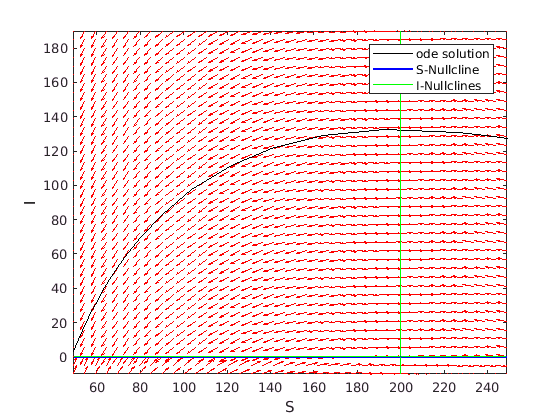

beta = .003;
gamma = .6;
N = 400;
percent_sick = .3;
x0 = N*([1,0] + [-1,1]*percent_sick);

f = @(x1,x2) -beta*x1.*x2;
g = @(x1,x2) x2.*(beta*x1 - gamma);
%% A configurable phase plot
ax = axes;
phasePlot({f,g},x0,[49,-10],ax)

$\frac{d\textnormal{S}}{dt}$ is negative where $\text{I}$ and $\text{S}$ are positive. This means $\text{S}$ decreases as quickly long as both $\text{S}$ and $I$ are larger than one. But if $0 \leq S \leq \frac{\gamma}{\beta}$  and $\text{I}$ is positive then $\frac{d\textnormal{I}}{dt}
$ is negative. Since this region this bound on the left by a $\text{I}$-axis and on the bottom by an  equilibrium line and both $\frac{d\text{I}}{dt}$ and $\frac{d\text{S}}{dt}$ are negative the solutions go to the equilibrium line and $\text{I}$ goes to zero.

## Model 2

 But sick people exist and so far as we can tell are not going away to quickly, not all of dieseases kill the population until they can't persist anymore (e.g. the common cold). To solve this we introduce the following modifications to $\frac{d\text{S}}{dt}$ we add $\nu \, R$ to allow survivors to become susceptible. The resulting system.

 
$$\begin{cases} \frac{d\text{S}}{dt} = -\beta \, \text{IS} + \nu \text{R} \\ \frac{d\text{I}}{dt} = \text{I} (\beta \, \text{S} - \gamma) \\ \frac{d\text{R}}{dt} = \gamma \, \text{I} - \nu \, \text{R} \end{cases}$$


Again $I + S + R = N$ is constant so for a fixed value of N we have

 
$$\begin{cases} \frac{d\text{S}}{dt} =  -\beta\text{SI} + \nu \,(\text{N - I -S}) \\\ \frac{d\text{I}}{dt} = \text{I}(\beta\text{S} - \gamma) \end{cases}$$
 

One equilibrium point has $\text{S = N}$ and $\text{I = 0}$(no sick people so no infections), it is attractive for $\text{N} \leq \frac{\gamma}{\beta}}$  and saddle for $\frac{\gamma}{\beta} < \text{N}$. The other equilibrium point has $\text{S} = \frac{\gamma}{\beta}$ and $\text{I}$ is a linear function of $\text{N}$. The equilibrium point with the given values for $\gamma, \nu$ and $\beta$ is a saddle for roughly $\text{N} < 200$ and $3800 < \text{N}$ and a spiral sink for all other values.  The graph of the determinant of the eigenvalue equation of the Jacobian at that point demonstrates this.

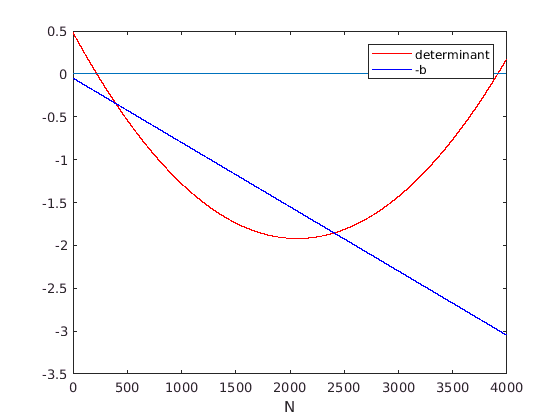

clc;clear;
beta = .003;
gamma = .6;
nu = .2;

N = linspace(0,4000,10000);
K = @(N) (beta.*N - gamma)./(gamma + nu);
plot(N,nu^2.*(K(N) +1).^2 - nu*4.*K(N).*(nu + gamma),'r',N,-nu*(K(N) + 1),'b',[0,4000],[0,0]);
legend('determinant','-b')
xlabel('N')

We show the vector field.

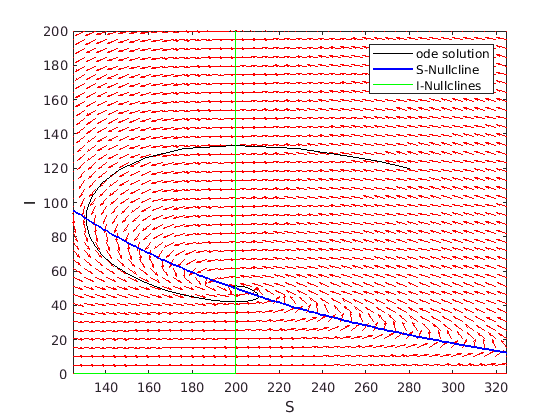

beta = .003;
gamma = .6;
nu = .2;
N = 400;
percent_sick = .3;
x0 = N*([1,0] + [-1,1]*percent_sick);

f = @(x1,x2) -beta*x1.*x2 + nu*(N - x1 - x2);
g = @(x1,x2) x2.*(beta.*x1 - gamma);
figure
ax2 = axes;
phasePlot({f,g},x0,[125,0],ax2)